# ΨΗΦΙΑΚΕΣ ΤΗΛΕΠΙΚΟΙΝΩΝΙΕΣ

## 1ο σετ Εργαστηριακών Ασκήσεων 

Λουδάρος Ιωάννης - ΑΜ 1067400

% Μεταφορά του Current Folder στον κατάλογο του αρχείου ώστε να υπάρχει
% πρόσβαση στις απαιτούμενες συναρτήσεις.

cd(fileparts(matlab.desktop.editor.getActiveFilename))

### Μέρος A

#### Η πηγή 

image = imread('parrot.png');

image_stream = reshape(image,1,[])

image_stream = 1×30000 uint8 row vector
     0     0     0    17     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    17    17    51   153   204   136    17     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


binary_image_stream = reshape((dec2bin(typecast(image(:),'uint8'),4)-'0').',1,[])

binary_image_stream =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


#### 1.a. Συχνότητα Εμφάνισης τιμών στο Μητρώο 

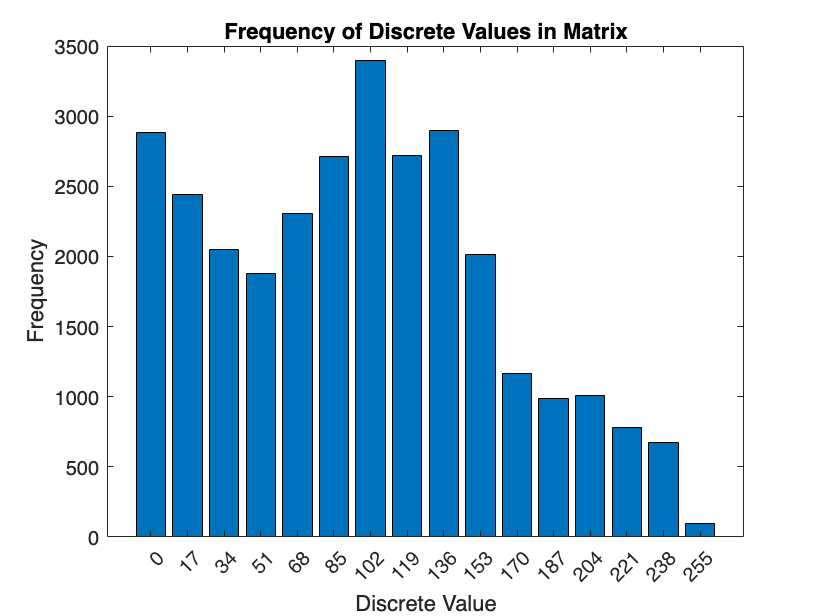

% Get the unique values in the matrix
unique_values = unique(image);

% Count the occurrences of each unique value
frequency = zeros(size(unique_values));
for i = 1:size(image, 1)
    for j = 1:size(image, 2)
        frequency(unique_values == image(i, j)) = frequency(unique_values == image(i, j)) + 1;
    end
end

% Create a bar graph to make the frequencies easily readable
bar(unique_values, frequency);
xticks(unique_values);
xticklabels(unique_values);
xlabel('Discrete Value');
ylabel('Frequency');
title('Frequency of Discrete Values in Matrix');

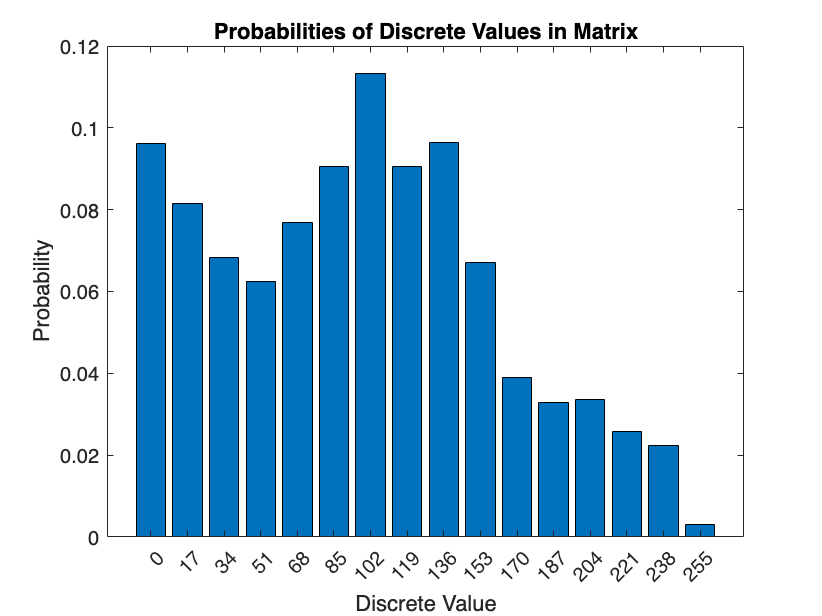

% Get the probability of each integer for the huffman dict later
probability = frequency./ (200*150);

% Create a bar graph to make the probabilities easily readable
bar(unique_values, probability);
xticks(unique_values);
xticklabels(unique_values);
xlabel('Discrete Value');
ylabel('Probability');
title('Probabilities of Discrete Values in Matrix');

#### 1.b. Κωδικοποίηση Huffman

% Create a dictionary for the encoding
[dict, avglen] = huffmandict(unique_values, probability)

dict = 16×2 cell array
    {[  0]}    {[        1 1 0]}
    {[ 17]}    {[      0 0 1 0]}
    {[ 34]}    {[      0 1 0 0]}
    {[ 51]}    {[      0 1 1 1]}
    {[ 68]}    {[      0 0 1 1]}
    {[ 85]}    {[      0 0 0 0]}
    {[102]}    {[        1 0 0]}
    {[119]}    {[        1 1 1]}
    {[136]}    {[        1 0 1]}
    {[153]}    {[      0 1 0 1]}
    {[170]}    {[    0 0 0 1 1]}
    {[187]}    {[    0 1 1 0 1]}
    {[204]}    {[    0 1 1 0 0]}
    {[221]}    {[  0 0 0 1 0 0]}
    {[238]}    {[0 0 0 1 0 1 0]}
    {[255]}    {[0 0 0 1 0 1 1]}


avglen = 3.8374


% Encode the Source
encoded_image_stream = huffmanenco(image_stream, dict);

% Compute the entropy
entropy = -sum(probability .* log2(probability))

entropy = 3.7831


% Copmute efficiency 
efficiency = entropy/avglen

efficiency = 0.9859

# L E G A C Y   C O N T E N T

#### LloydMax 

[Άνοιγμα Ορισμού](matlab:open('./LloydMax.m'))

Κατασκευάστηκε η παρακάτω συνάρτηση 

Είσοδοι:

- $x$ : Το σήμα εισόδου υπό την μορφή διανύσματος

- $N
$: Ο αριθμός των bits/sample που θα χρησιμοποιηθούν

- $max_{value$ : Η μέγιστη αποδεκτή τιμή του σήματος εισόδου

- $min_{value}$ : Η ελάχιστη αποδεκτή τιμή του σήματος εισόδου

Έξοδοι:

- $x_q$ : Το κωδικοποιημένο διάνυσμα εξόδου μετά από $K_{max}$ επαναλήψεις του αλγορίθμου

- $\text{centers}$ : Τα κέντρα των περιοχών κβάντισης μετά από $K_{max}$ επαναλήψεις του αλγορίθμου.

- $D$ : Διάνυσμα που περιέχει τις τιμές [$D_1 : D_{K_{max}}$], όπου το $D_i$ αντιστοιχεί στη μέση παραμόρφωση την i-οστή επανάληψη του αλγορίθμου

Η συνάρτηση ορίζεται στο αρχείο LloydMax.m που βρίσκεται στον ίδιο κατάλογο με το παρόν αρχείο.

**Παράδειγμα χρήσης:**

min_value = 1;
max_value = 100;
N = 4;
x = 120*rand(1, 100)-10

x =     9.4619   85.3141   27.3458   53.4240    9.8778   62.2378   21.5566   68.4895   72.7057   79.7782   44.0650    0.0586   17.4772   99.6005    8.2854   89.0980   54.6011  109.5362   -0.6189   43.1214    2.7983  105.4278   -9.4439   82.9893   88.0764   94.2434    0.1323   37.9739   21.1844   86.0082   41.7697   99.2777   11.8216   21.6563    7.4647    6.3282   94.3151   59.5646   55.9832    7.3946   92.3637   64.6466   32.1143   51.5899   38.2170   -0.8840   18.7899    4.7983   12.0689   18.7943






[xq, centers, D] = LloydMax(x, N, min_value, max_value)

Unrecognized function or variable 'LloydMax'.

#### Adaptive Delta Modulation

([Άνοιγμα Ορισμών](matlab:open('./adm.m')))

Για την Προσαρμοστική Κωδικοποίηση Δέλτα δημιουργήθηκαν 2 συναρτήσεις.

**1. O Κωδικοποιητής **

Είσοδοι:

- x : Το αρχικό μας σήμα.

- M : Ο παράγοντας υπερδειγματοληψίας.

Έξοδοι:

- xq : Το κωδικοποιημένο σήμα.

**2. Ο Αποκωδικοποιητής**

Είσοδοι:

- xq : Το κωδικοποιημένο σήμα που παραλάβαμε.

- M: Ο παράγωντας υπερδειγματοληψίας.

Έξοδοι:

- decoded : Το αποκωδικοποιημένο σήμα.

**Παράδειγμα χρήσης:**

min_value = 1;
max_value = 100;
N = 4;
x = 120*rand(1, 100)-10




[xq, centers, D] = LloydMax(x, N, min_value, max_value)

#### Πηγές που θα χρησιμοποιηθούν

**Α. AR(1) διαδικασία**

L=10000;
x=randn(L,1);
a1=0.9;
a2=0.01;

ar1 = filter(1,[1; -a1], x)
ar2 = filter(1,[1; -a2], x)


**Β. Εικόνα**

load cameraman.mat
imshow(uint8(i));
x=i(:);
x=((x-128)/128);

#### Ερώτηση 1